Last inn Iris data

clear;
x1 = load('IrisData/class_1','-ascii'); % Iris-setosa 50x4
x2 = load('IrisData/class_2','-ascii'); % Iris-versicolor 50x4
x3 = load('IrisData/class_3','-ascii'); % Iris-virginica 50x4
dim_labels = {'Sepal Length (cm)', 'Sepal Width (cm)', 'Petal Length (cm)', 'Petal Width (cm)'};
class_labels = {'Iris-setosa', 'Iris-versicolor', 'Iris-virginica'};

Visualisering av Iris data

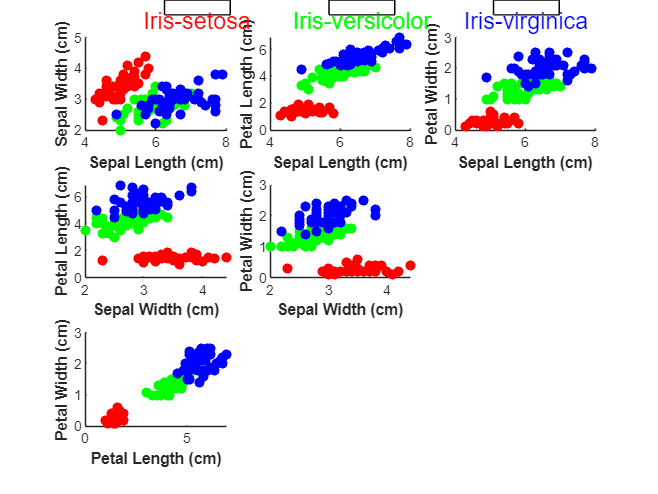

figure;
annotation('textbox', [0.25, 0.97, 0.1, 0.03], 'String', '• Iris-setosa', 'FontSize', 14, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'r');
annotation('textbox', [0.5, 0.97, 0.1, 0.03], 'String', '• Iris-versicolor', 'FontSize', 14, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'g');
annotation('textbox', [0.75, 0.97, 0.1, 0.03], 'String', '• Iris-virginica', 'FontSize', 14, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'b');
for i = 1:3
    for j = i+1:4
        subplot(3, 3, (i-1)*3 + j-i);
        scatter(x1(:,i), x1(:,j), 'r', 'filled');
        hold on;
        scatter(x2(:,i), x2(:,j), 'g', 'filled');
        scatter(x3(:,i), x3(:,j), 'b', 'filled');
        xlabel(dim_labels{i},'FontWeight','bold');
        ylabel(dim_labels{j},'FontWeight','bold');
    end
end
hold off;

Oppgave 1

a) 30 første samplene til trening + 20 siste til testing

x1_train=x1(1:30,:); x1_test=x1(31:50,:);
x2_train=x2(1:30,:); x2_test=x2(31:50,:);
x3_train=x3(1:30,:); x3_test=x3(31:50,:);

b) + c)

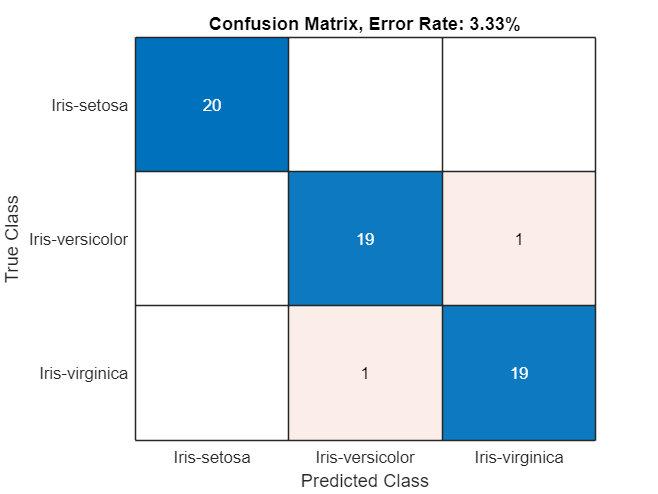

X_train = [x1_train; x2_train; x3_train];
Y_train = [ones(size(x1_train, 1), 1); ...
           2 * ones(size(x2_train, 1), 1); ...
           3 * ones(size(x3_train, 1), 1)];

IrisModel = fitcdiscr(X_train, Y_train);

X_test = [x1_test; x2_test; x3_test];
Y_test_true = [ones(size(x1_test, 1), 1); ...
               2 * ones(size(x2_test, 1), 1); ...
               3 * ones(size(x3_test, 1), 1)];

Y_test_pred = predict(IrisModel, X_test);

confusion_matrix = confusionmat(Y_test_true, Y_test_pred);
error_rate = 1 - sum(diag(confusion_matrix)) / sum(confusion_matrix(:));

figure;
confusionchart(confusion_matrix, class_labels);
title(['Confusion Matrix, Error Rate: ', num2str(round(error_rate * 100,2)), '%']);

d) 20 første samplene til testing + 30 siste til trening

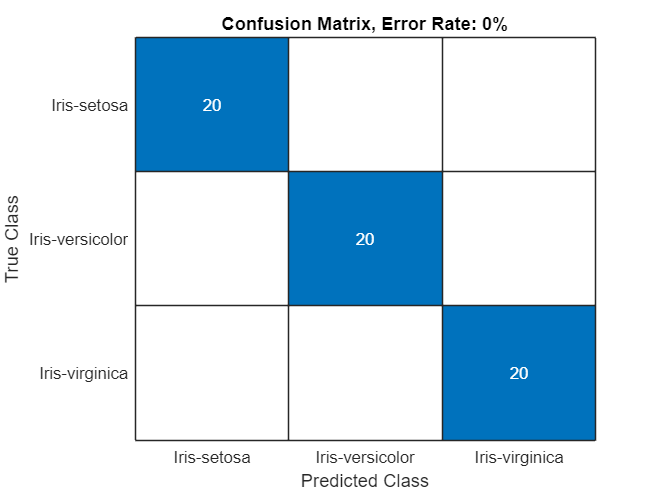

x1_train2 = x1(21:50, :); x1_test2 = x1(1:20, :);
x2_train2 = x2(21:50, :); x2_test2 = x2(1:20, :);
x3_train2 = x3(21:50, :); x3_test2 = x3(1:20, :);

X_train2 = [x1_train2; x2_train2; x3_train2];
Y_train2 = [ones(size(x1_train2, 1), 1); ...
           2 * ones(size(x2_train2, 1), 1); ...
           3 * ones(size(x3_train2, 1), 1)];

IrisModel2 = fitcdiscr(X_train2, Y_train2);

X_test2 = [x1_test2; x2_test2; x3_test2];
Y_test_true2 = [ones(size(x1_test2, 1), 1); ...
               2 * ones(size(x2_test2, 1), 1); ...
               3 * ones(size(x3_test2, 1), 1)];

Y_test_pred2 = predict(IrisModel2, X_test2);

confusion_matrix2 = confusionmat(Y_test_true2, Y_test_pred2);
error_rate2 = 1 - sum(diag(confusion_matrix2)) / sum(confusion_matrix2(:));

figure;
confusionchart(confusion_matrix2, class_labels);
title(['Confusion Matrix, Error Rate: ', num2str(round(error_rate2 * 100, 2)), '%']);

Oppgave 2

a)

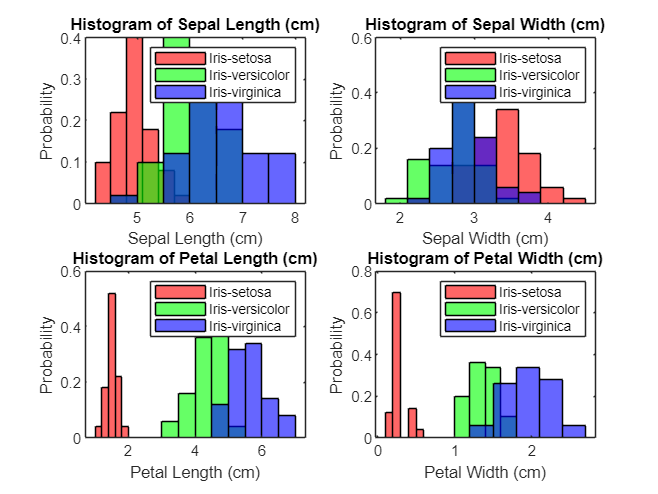

figure;
for i = 1:size(x1, 2)
    subplot(2, 2, i);
    histogram(x1(:, i), 'Normalization', 'probability', 'DisplayName', class_labels{1},'FaceColor','r');
    hold on;
    histogram(x2(:, i), 'Normalization', 'probability', 'DisplayName', class_labels{2},'FaceColor','g');
    histogram(x3(:, i), 'Normalization', 'probability', 'DisplayName', class_labels{3},'FaceColor','b');
    hold off;
    title(['Histogram of ', dim_labels{i}]);
    xlabel(dim_labels{i});
    ylabel('Probability');
    legend;
end

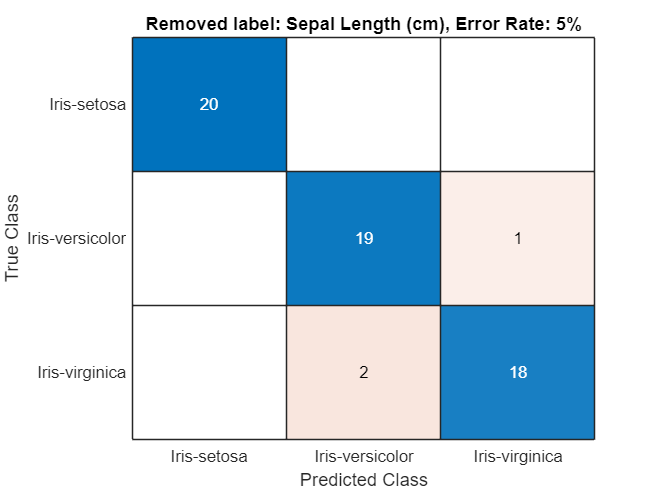


overlap = zeros(4, 4);
for i = 1:4
    for j = 1:4
        overlap(i, j) = sum(min(x1(:, i), x2(:, j))) + sum(min(x1(:, i), x3(:, j))) + sum(min(x2(:, i), x3(:, j)));
    end
end

overlap = overlap - diag(diag(overlap));
[~, feature_to_remove] = max(overlap(:));
[feature_idx1, ~] = ind2sub(size(overlap), feature_to_remove);

remaining_features = setdiff(1:4, feature_idx1);

x1_train3 = x1(1:30, remaining_features); x1_test3 = x1(31:50, remaining_features);
x2_train3 = x2(1:30, remaining_features); x2_test3 = x2(31:50, remaining_features);
x3_train3 = x3(1:30, remaining_features); x3_test3 = x3(31:50, remaining_features);

X_train3 = [x1_train3; x2_train3; x3_train3];
Y_train3 = [ones(30, 1); 2 * ones(30, 1); 3 * ones(30, 1)];

IrisModel3 = fitcdiscr(X_train3, Y_train3);

X_test3 = [x1_test3; x2_test3; x3_test3];
Y_test_true3 = [ones(20, 1); 2 * ones(20, 1); 3 * ones(20, 1)];

Y_test_pred3 = predict(IrisModel3, X_test3);

confusion_matrix3 = confusionmat(Y_test_true3, Y_test_pred3);
error_rate3 = 1 - sum(diag(confusion_matrix3)) / sum(confusion_matrix3(:));

figure;
confusionchart(confusion_matrix3, class_labels);
title(['Removed label: ',dim_labels{feature_idx1}, ', Error Rate: ', num2str(round(error_rate3 * 100, 2)), '%']);

2 remaining

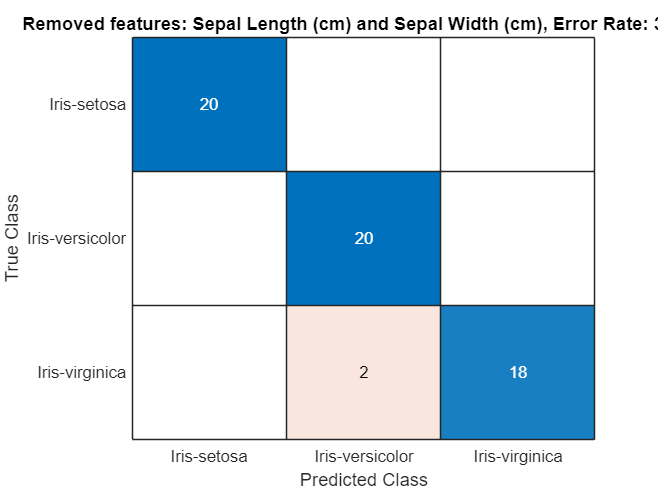

[~, features_to_remove] = maxk(overlap(:), 2);
[feature_idx1, ~] = ind2sub(size(overlap), features_to_remove);
remaining_features = setdiff(1:4, feature_idx1);

x1_train4 = x1(1:30, remaining_features); x1_test4 = x1(31:50, remaining_features);
x2_train4 = x2(1:30, remaining_features); x2_test4 = x2(31:50, remaining_features);
x3_train4 = x3(1:30, remaining_features); x3_test4 = x3(31:50, remaining_features);

X_train4 = [x1_train4; x2_train4; x3_train4];
Y_train4 = [ones(30, 1); 2 * ones(30, 1); 3 * ones(30, 1)];

IrisModel4 = fitcdiscr(X_train4, Y_train4);

X_test4 = [x1_test4; x2_test4; x3_test4];
Y_test_true4 = [ones(20, 1); 2 * ones(20, 1); 3 * ones(20, 1)];

Y_test_pred4 = predict(IrisModel4, X_test4);

confusion_matrix4 = confusionmat(Y_test_true4, Y_test_pred4);
error_rate4 = 1 - sum(diag(confusion_matrix4)) / sum(confusion_matrix4(:));

figure;
confusionchart(confusion_matrix4, class_labels);
title(['Removed features: ', dim_labels{feature_idx1(1)}, ' and ', dim_labels{feature_idx1(2)}, ', Error Rate: ', num2str(round(error_rate4 * 100, 2)), '%']);

1 remaining (least overlap)

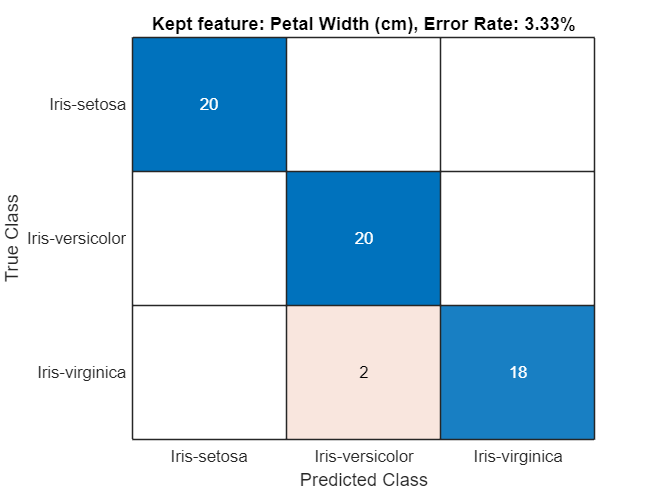

overlap_no_diagonal = overlap;
overlap_no_diagonal(logical(eye(size(overlap_no_diagonal)))) = Inf;
[~, feature_to_keep] = min(overlap_no_diagonal(:));

remaining_features = feature_to_keep;

x1_train5 = x1(1:30, remaining_features); x1_test5 = x1(31:50, remaining_features);
x2_train5 = x2(1:30, remaining_features); x2_test5 = x2(31:50, remaining_features);
x3_train5 = x3(1:30, remaining_features); x3_test5 = x3(31:50, remaining_features);

X_train5 = [x1_train5; x2_train5; x3_train5];
Y_train5 = [ones(30, 1); 2 * ones(30, 1); 3 * ones(30, 1)];

IrisModel5 = fitcdiscr(X_train5, Y_train5);

X_test5 = [x1_test5; x2_test5; x3_test5];
Y_test_true5 = [ones(20, 1); 2 * ones(20, 1); 3 * ones(20, 1)];

Y_test_pred5 = predict(IrisModel5, X_test5);

confusion_matrix5 = confusionmat(Y_test_true5, Y_test_pred5);
error_rate5 = 1 - sum(diag(confusion_matrix5)) / sum(confusion_matrix5(:));

figure;
confusionchart(confusion_matrix5, class_labels);
title(['Kept feature: ', dim_labels{feature_to_keep}, ', Error Rate: ', num2str(round(error_rate5 * 100, 2)), '%']);